## Introduction to **Bio-Informatics** 2022

# **Assignment 3: Hidden Markov Models **

**Chiara Paglioni (i6249782)**

The new corona virus contains just a few genes, one of them is a nucleocapsid phosphoprotein, known as N.  The accession code for the RNA for the whole Coronavirus 2 genome is NC_045512.  The N protein can be found in the region 28274...29533.

**Retrieve Data from Gene Bank**

First retrieve the full sequence, extract the part of the sequence for the N protein and make a nucleotide density plot with a suitable window size. Showing the distribution of each base across the sequence and also the AT and GC pairs. 

clear;
data = getgenbank('NC_045512', 'SequenceOnly', true)

data = 'ATTAAAGGTTTATACCTTCCCAGGTAACAAACCAACCAACTTTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGGCTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCGTCTATCTTCTGCAGGCTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTTTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGTCTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGCGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCGGATGCTCGAACTGCACCTCATGGTCATGTTATGGTTGAGCTGGTAGCAGAACTCGAAGGCATTCAGTACGGTCGTAGTGGTGAGACACTTGGTGTCCTTGTCCCTCATGTGGGCGAAATACCAGTGGCTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCCGATCTAAAGTCATTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTTACCCGTGAACTCATGCGTGAGCTTAACGGAGGGGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCACGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAGAGGGGTGTATACTGCTGCCGTGAACATGAGCATGAAATTGCTTGGTACACGG

% Get protein from sequence
protein = data(28274:29533)

protein = 'ATGTCTGATAATGGACCCCAAAATCAGCGAAATGCACCCCGCATTACGTTTGGTGGACCCTCAGATTCAACTGGCAGTAACCAGAATGGAGAACGCAGTGGGGCGCGATCAAAACAACGTCGGCCCCAAGGTTTACCCAATAATACTGCGTCTTGGTTCACCGCTCTCACTCAACATGGCAAGGAAGACCTTAAATTCCCTCGAGGACAAGGCGTTCCAATTAACACCAATAGCAGTCCAGATGACCAAATTGGCTACTACCGAAGAGCTACCAGACGAATTCGTGGTGGTGACGGTAAAATGAAAGATCTCAGTCCAAGATGGTATTTCTACTACCTAGGAACTGGGCCAGAAGCTGGACTTCCCTATGGTGCTAACAAAGACGGCATCATATGGGTTGCAACTGAGGGAGCCTTGAATACACCAAAAGATCACATTGGCACCCGCAATCCTGCTAACAATGCTGCAATCGTGCTACAACTTCCTCAAGGAACAACATTGCCAAAAGGCTTCTACGCAGAAGGGAGCAGAGGCGGCAGTCAAGCCTCTTCTCGTTCCTCATCACGTAGTCGCAACAGTTCAAGAAATTCAACTCCAGGCAGCAGTAGGGGAACTTCTCCTGCTAGAATGGCTGGCAATGGCGGTGATGCTGCTCTTGCTTTGCTGCTGCTTGACAGATTGAACCAGCTTGAGAGCAAAATGTCTGGTAAAGGCCAACAACAACAAGGCCAAACTGTCACTAAGAAATCTGCTGCTGAGGCTTCTAAGAAGCCTCGGCAAAAACGTACTGCCACTAAAGCATACAATGTAACACAAGCTTTCGGCAGACGTGGTCCAGAACAAACCCAAGGAAATTTTGGGGACCAGGAACTAATCAGACAAGGAACTGATTACAAACATTGGCCGCAAATTGCACAATTTGCCCCCAGCGCTTCAGCGTTCTTCGGAATGTCGCGCATTGGCATGGAAGTCACACCTTCGGGAACGTG

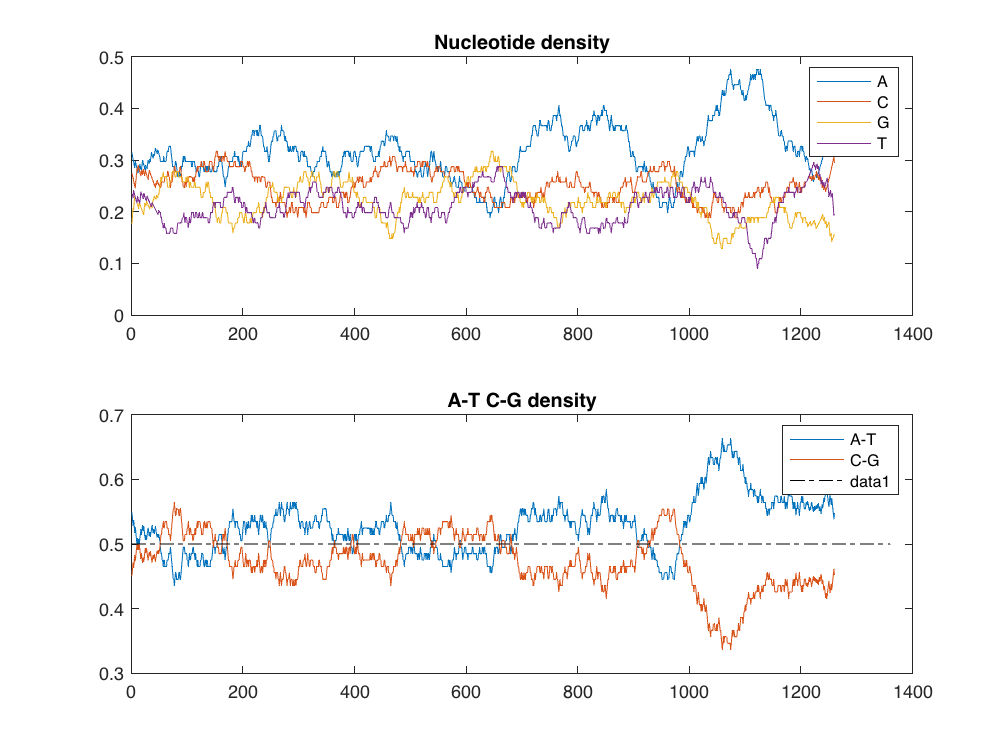

lengthProtein = length(protein);
% Density plot
figure;
[Density, HighCG]  = ntdensity(protein, 'Window', 100, 'CGThreshold', 0.5);

## HMM: 2 States 

For the A-T C-G plot we determine the following two states for the Hidden Markov Model:

**        State 1**: High CG

**        State 2**: High AT

Moreover, the transition matrix **T** and probability matrix **E** are computed.

% State 1: locations in the protein with high CG
HighCG

HighCG =     52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101


% Count occurrences of state 1 and state 2 
lengthHighCG = length(HighCG);
lengthHighAT = lengthProtein - lengthHighCG;
prob_HighCG = lengthHighCG/lengthProtein;
prob_HighAT = lengthHighAT/lengthProtein;
states_matrix = [[lengthHighCG, lengthHighAT]; 
                 [prob_HighCG, prob_HighAT]];
states_table = table(states_matrix);
states_table.Row = ["Occurrences", "Probabilities"];
states_table.Properties.VariableNames = "State1 and State2"

states_table = 2×1 table
                     State1 and State2 
                     __________________

    Occurrences          354        906
    Probabilities    0.28095    0.71905


% Estimate how many times we switch from state 1 to state 2
switches_count = 0; 
differences = diff(HighCG);
switches = zeros(1, 16);

for s = 1 : length(differences)
    if not(differences(s) == 1)
        switches_count = switches_count + 1;
        switches(switches_count) = HighCG(s);
    end
end   
switches_count

switches_count = 16

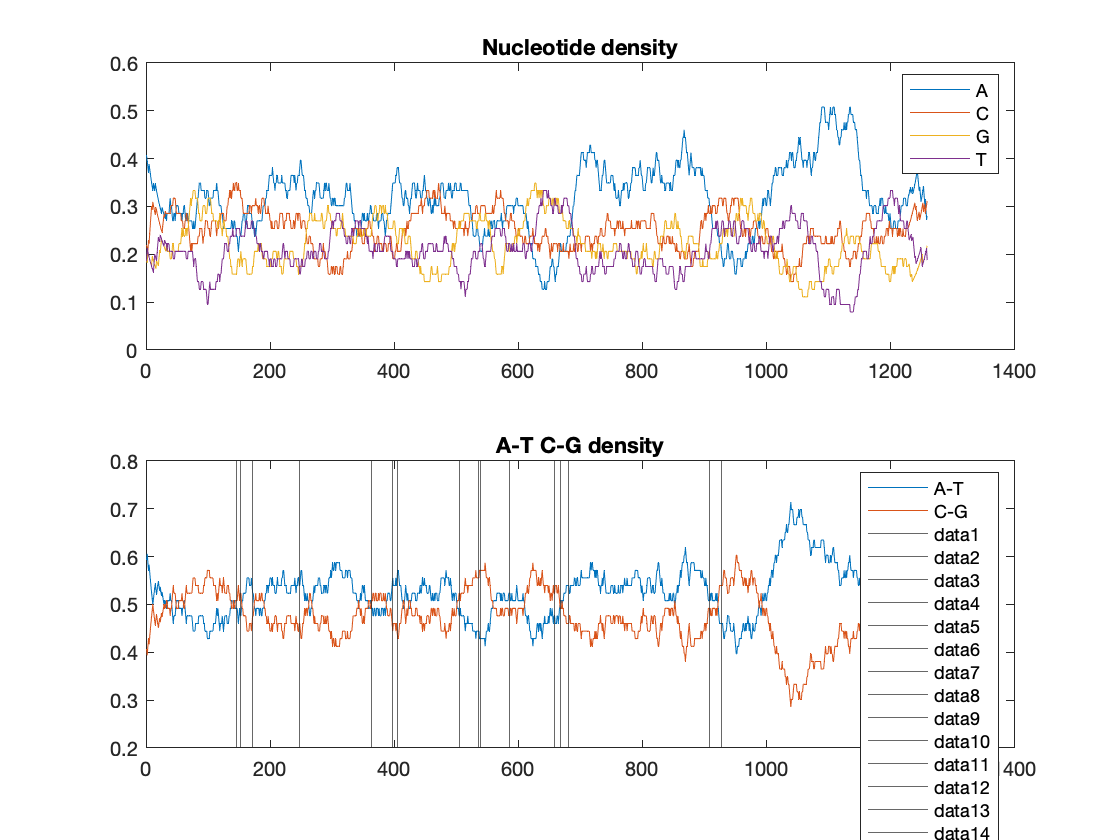

% Plot density with lines where state 1 and state 2 switch
figure;
ntdensity(protein, 'Window', lengthProtein/20)
for l = 1 : length(switches)
    xline(switches(l))
end    

From the previous A-T C-G density plot we can observe the switches between thw two different states. The black vertical lines separate one state from the other. 

Moreover, looking at the plot of the distribution of bases, we identify the 2 regions with different patterns of expression. Calculate the proportion of each base in each of these two regions and put them together to make an initial estimate for E.

% Estimate E for state 1
% Occurrences of all the bases in State 1
occ1_A = 0;
occ1_C = 0;
occ1_G = 0;
occ1_T = 0;

for x = 1 : lengthHighCG
    if protein(HighCG(x)) == 'A'
        occ1_A = occ1_A + 1;
    elseif protein(HighCG(x)) == 'C'
        occ1_C = occ1_C + 1;
    elseif protein(HighCG(x)) == 'G'
        occ1_G = occ1_G + 1;
    else
        occ1_T = occ1_T + 1;
    end    
end  
% Calculate probabilities of all the bases in state 1
prob1_A = occ1_A/lengthHighCG;
prob1_C = occ1_C/lengthHighCG;
prob1_G = occ1_G/lengthHighCG;
prob1_T = occ1_T/lengthHighCG;
% Estimate E for state 2
% Occurrences of all the bases in State 2
occ2_A = 0;
occ2_C = 0;
occ2_G = 0;
occ2_T = 0;

% Variable used to check in which state we are
match = false; 

for x = 1 : lengthProtein
    match = false;
    
    for z = 1 : lengthHighCG
        % Check if the base in in State 1 or State 2
        if x == HighCG(z) 
           match = true;
           break  
        end
    end 

    if match == false
        % Check which base is the current one and update counter
        if protein(x) == 'A'
            occ2_A = occ2_A + 1;
        elseif protein(x) == 'C'
            occ2_C = occ2_C + 1;
        elseif protein(x) == 'G'
            occ2_G = occ2_G + 1;
        else
            occ2_T = occ2_T + 1;
        end
    end      
end  
% Calculate probabilities of all the bases in state 1
prob2_A = occ2_A/lengthHighAT;
prob2_C = occ2_C/lengthHighAT;
prob2_G = occ2_G/lengthHighAT;
prob2_T = occ2_T/lengthHighAT;
% Construct matrix E by merging the probabilities of the two states together
E = [[prob1_A, prob1_C, prob1_G, prob1_T];
     [prob2_A, prob2_C, prob2_G, prob2_T]]

E =     0.2429    0.2768    0.2627    0.2175
    0.3466    0.2395    0.2064    0.2075


T = [[prob_HighCG, (1-prob_HighCG)];
     [(1-prob_HighAT), prob_HighAT]]

T =     0.2810    0.7190
    0.2810    0.7190


 Before we can train the hidden Markov model we need to turn the sequence into integers instead of characters – use **nt2int** to do this. 

int_protein = nt2int(protein)

int_protein = 1×1260 uint8 row vector
   1   4   3   4   2   4   3   1   4   1   1   4   3   3   1   2   2   2   2   1   1   1   1   4   2   1   3   2   3   1   1   1   4   3   2   1   2   2   2   2   3   2   1   4   4   1   2   3   4   4


 Now we can train our hmm using **hmmtrain** (NB. to speed this up you can change the tolerance parameter). This gives us the learnt E and T matrices based on this sequence. How do these vary from your initial guesses? 

[ESTTR, ESTEMIT] = hmmtrain(int_protein, T, E)

ESTTR =     0.6181    0.3819
    0.3358    0.6642


ESTEMIT =     0.0001    0.2656    0.2919    0.4423
    0.5968    0.2363    0.1609    0.0061


 To look at how this HMM would segment your sequence, use the function **hmmviterbi** to generate the estimated states from this sequence.  

STATES = hmmviterbi(int_protein, ESTTR, ESTEMIT)

STATES =      2     1     1     1     1     1     1     2     1     2     2     1     1     1     2     2     2     2     2     2     2     2     2     1     1     2     2     2     2     2     2     2     1     1     1     2     2     2     2     2     2     2     2     1     1     2     1     1     1     1


 Using the **hold** function add these states onto the **ntdensity** plot. How does this help your interpretation of the states? Can you explain what the two states mean? 

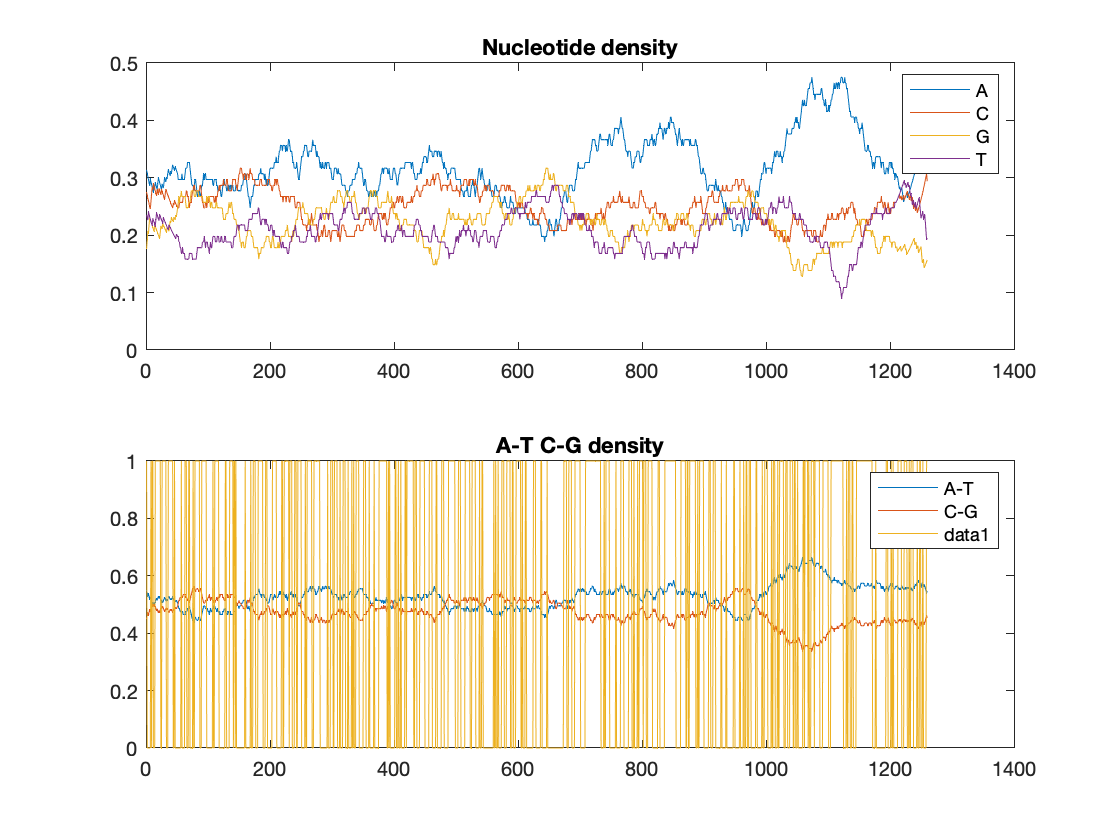

% Too many occurrences of 1 and 2???
figure;
ntdensity(protein, 'Window', 100);
hold on;
plot(STATES-1)

## HMM: 3 States 

In order to implement a Hidden Markov Model with 3 states, the nucleotide A is exploited. The following are the states derived for this model:

**        State 1**: (from 0 to 610 AND after 1190 approximatelly) --> **average levels of A (around 0.25)**

**        State 2**: (from 610 to 690 AND from 920 to 1000 approximatelly) --> **low A**

        **State 3: **(from 690 to 920 AND from 1000 to 1190 approximatelly) --> **high A**

Moreover, the transition matrix **T** and probability matrix **E** are computed.

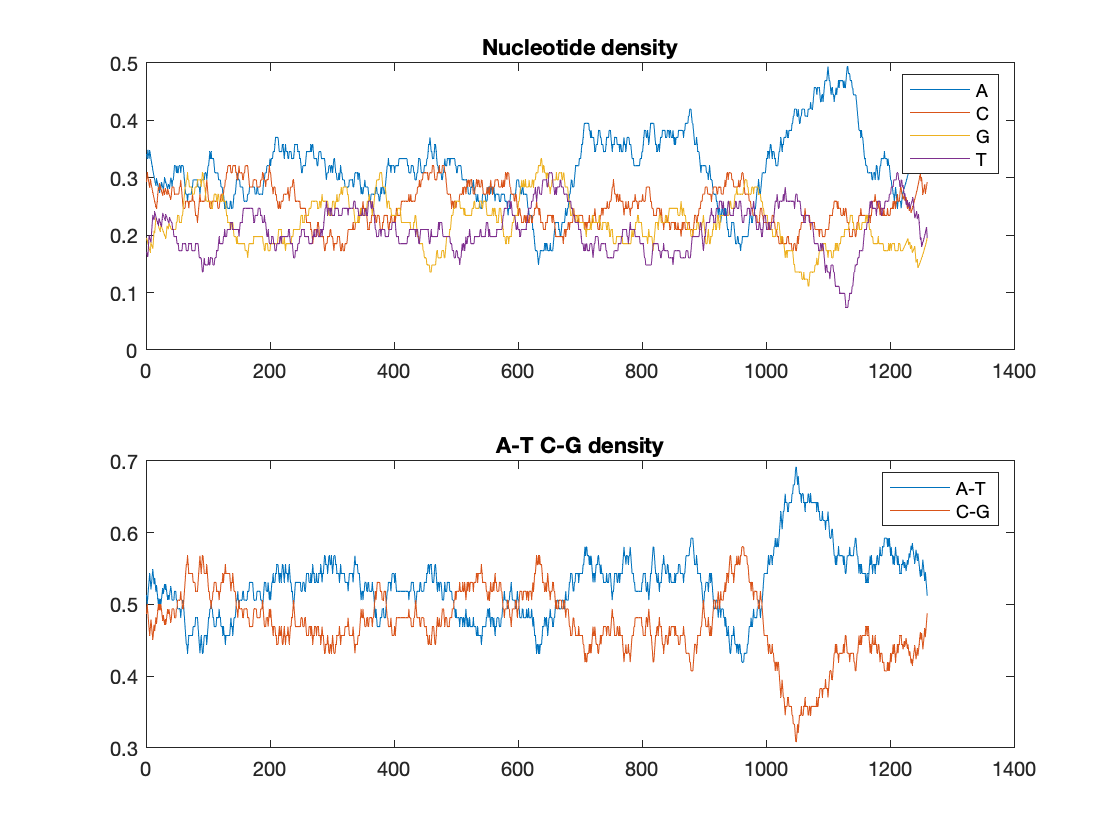

Density_3s = struct with fields:
    A: [0.3415 0.3333 0.3488 0.3409 0.3333 0.3478 0.3404 0.3333 0.3265 0.3200 0.3137 0.3077 0.3019 0.2963 0.2909 0.2857 0.2982 0.2931 0.2881 0.2833 0.2787 0.2742 0.2857 0.2812 0.2923 0.2879 0.2836 0.2794 0.2899 0.3000 0.2958 0.2917 0.2877 0.2838 … ]
    C: [0.2927 0.3095 0.3023 0.2955 0.2889 0.2826 0.2979 0.2917 0.2857 0.2800 0.2745 0.2692 0.2642 0.2593 0.2545 0.2500 0.2456 0.2586 0.2712 0.2833 0.2787 0.2903 0.2857 0.2812 0.2769 0.2727 0.2687 0.2794 0.2754 0.2714 0.2817 0.2778 0.2740 0.2703 … ]
    G: [0.1951 0.1905 0.1860 0.1818 0.1778 0.1739 0.1702 0.1875 0.1837 0.1800 0.1765 0.1923 0.2075 0.2037 0.2182 0.2321 0.2281 0.2241 0.2203 0.2167 0.2131 0.2097 0.2063 0.2188 0.2154 0.2121 0.2090 0.2059 0.2029 0.2000 0.1972 0.1944 0.2055 0.2162 … ]
    T: [0.1707 0.1667 0.1628 0.1818 0.2000 0.1957 0.1915 0.1875 0.2041 0.2200 0.2353 0.2308 0.2264 0.2407 0.2364 0.2321 0.2281 0.2241 0.2203 0.2167 0.2295 0.2258 0.2222 0.2188 0.2154 0.2273 0.2388 0.2353 0.2319 0.2286

figure;
Density_3s = ntdensity(protein, 'Window', 80)

The approximate representation of the division f the different states is shown below: 

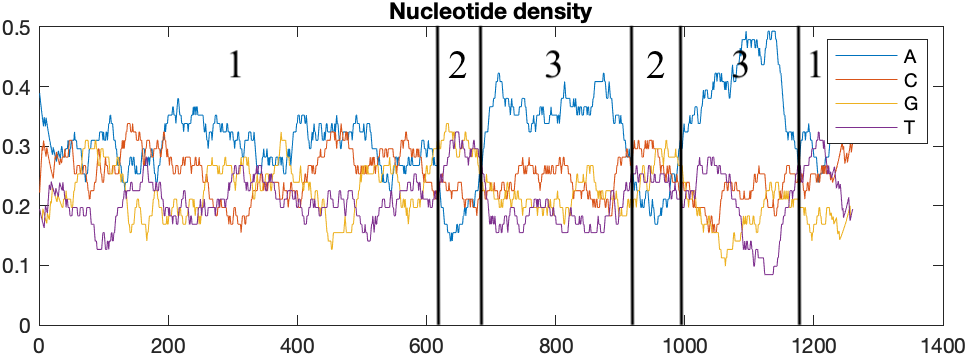

% STATE 1
occ31_A = sum(Density_3s.A(1:610)) + sum(Density_3s.A(1190:lengthProtein));
occ31_C = sum(Density_3s.C(1:610)) + sum(Density_3s.C(1190:lengthProtein));
occ31_G = sum(Density_3s.G(1:610)) + sum(Density_3s.G(1190:lengthProtein));
occ31_T = sum(Density_3s.T(1:610)) + sum(Density_3s.T(1190:lengthProtein));

% STATE 2
occ32_A = sum(Density_3s.A(610:690)) + sum(Density_3s.A(920:1000));
occ32_C = sum(Density_3s.C(610:690)) + sum(Density_3s.C(920:1000));
occ32_G = sum(Density_3s.G(610:690)) + sum(Density_3s.G(920:1000));
occ32_T = sum(Density_3s.T(610:690)) + sum(Density_3s.T(920:1000));

% STATE 3
occ33_A = sum(Density_3s.A(690:920)) + sum(Density_3s.A(1000:1190));
occ33_C = sum(Density_3s.C(690:920)) + sum(Density_3s.C(1000:1190));
occ33_G = sum(Density_3s.G(690:920)) + sum(Density_3s.G(1000:1190));
occ33_T = sum(Density_3s.T(690:920)) + sum(Density_3s.T(1000:1190));

% PROBABILITIES 
% STATE 1
prob31_A = occ31_A/sum(Density_3s.A);
prob31_C = occ31_C/sum(Density_3s.C);
prob31_G = occ31_G/sum(Density_3s.G);
prob31_T = occ31_T/sum(Density_3s.T);

% STATE 2
prob32_A = occ32_A/sum(Density_3s.A);
prob32_C = occ32_C/sum(Density_3s.C);
prob32_G = occ32_G/sum(Density_3s.G);
prob32_T = occ32_T/sum(Density_3s.T);

% STATE 3
prob33_A = occ33_A/sum(Density_3s.A);
prob33_C = occ33_C/sum(Density_3s.C);
prob33_G = occ33_G/sum(Density_3s.G);
prob33_T = occ33_T/sum(Density_3s.T);


% Plot data in a table
E_3 = [[prob31_A, prob31_C, prob31_G, prob31_T];
       [prob32_A, prob32_C, prob32_G, prob32_T];
       [prob33_A, prob33_C, prob33_G, prob33_T]]

E_3 =     0.5166    0.5664    0.5425    0.5437
    0.0905    0.1264    0.1597    0.1557
    0.3966    0.3112    0.3019    0.3050



% Sanity check (= 1)
sum([prob31_A, prob32_A, prob33_A]);
sum([prob31_C, prob32_C, prob33_C]);
sum([prob31_G, prob32_G, prob33_G]);
sum([prob31_T, prob32_T, prob33_T]);

% COMPUTE T
% STATE 1
state31to32 = 1/lengthProtein;
state31to33 = 0;
state31to31 = 1 - (state31to32 + state31to33);

% STATE 2
state32to31 = 0;
state32to33 = 2/lengthProtein;
state32to32 = 1 - (state32to31 + state32to33);

% STATE 3
state33to31 = 1/lengthProtein;
state33to32 = 1/lengthProtein;
state33to33 = 1 - (state33to31 + state33to32);

% Build transition matrix T
T_3 = [[state31to31, state31to32, state31to33];
       [state32to31, state32to32, state32to33];
       [state33to31, state33to32, state33to33]]

T_3 =     0.9992    0.0008         0
         0    0.9984    0.0016
    0.0008    0.0008    0.9984



% Train model based on the estimated T and E matrices
[ESTTR_3, ESTEMIT_3] = hmmtrain(int_protein, T_3, E_3)

ESTTR_3 =     0.7987    0.2013         0
         0    0.0005    0.9995
    0.5269    0.1759    0.2972


ESTEMIT_3 =     0.1299    0.2523    0.2981    0.3197
    0.2342    0.5106    0.2551    0.0000
    0.8677    0.0606    0.0000    0.0717


STATES_3 = hmmviterbi(int_protein, ESTTR_3, ESTEMIT_3)

STATES_3 =      1     1     1     1     1     1     2     3     1     2     3     1     1     2     3     1     1     1     2     3     3     3     3     1     2     3     1     1     2     3     3     3     1     1     2     3     1     1     1     1     1     2     3     1     1     1     1     1     1     1


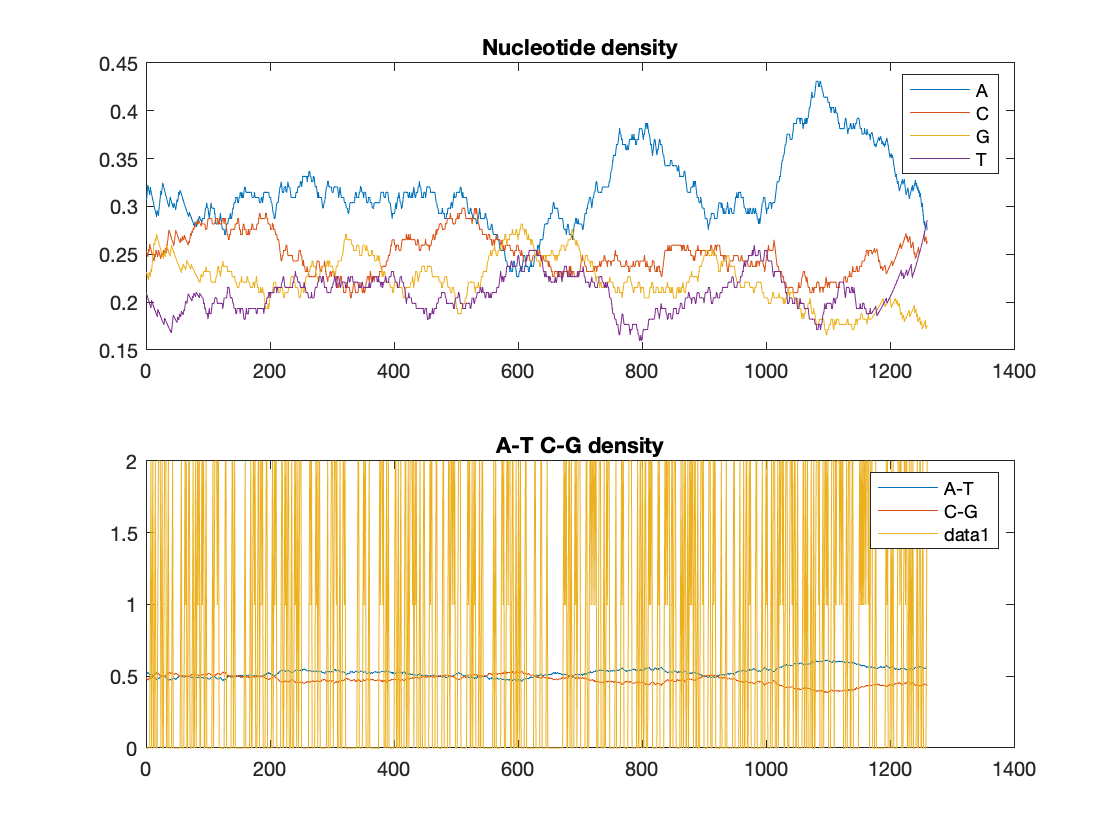


% Plot the resulting matrices E and T after training the model
figure;
ntdensity(protein, 'Window', 180);
hold on;
plot(STATES_3-1)

## HMM: 4 States

In order to implement a Hidden Markov Model with 4 states, the C bases is exploited. The following are the states derived for this model:

**        State 1**: (from 0 to 200 AND from 420 to 450 approximatelly) --> **T lower than 0.2 AND C higher than 0.25  **

**        State 2**: (from 200 to 420 AND from 600 to 780 AND from 900 to 1020 AND after 1050  approximatelly) --> **T higher than 0.2 AND C lower than 0.25 **

  **      State 3: **(from 420 to 600 AND from 820 to 900 approximatelly) -->** T higher than 0.2 AND C higher than 0.25 **

        **State 4: **(from 780 to 820 AND from 1020 to 1050 approximatelly) --> **T lower than 0.2 AND  C lower than 0.25 **

Moreover, the transition matrix **T** and probability matrix **E** are computed.

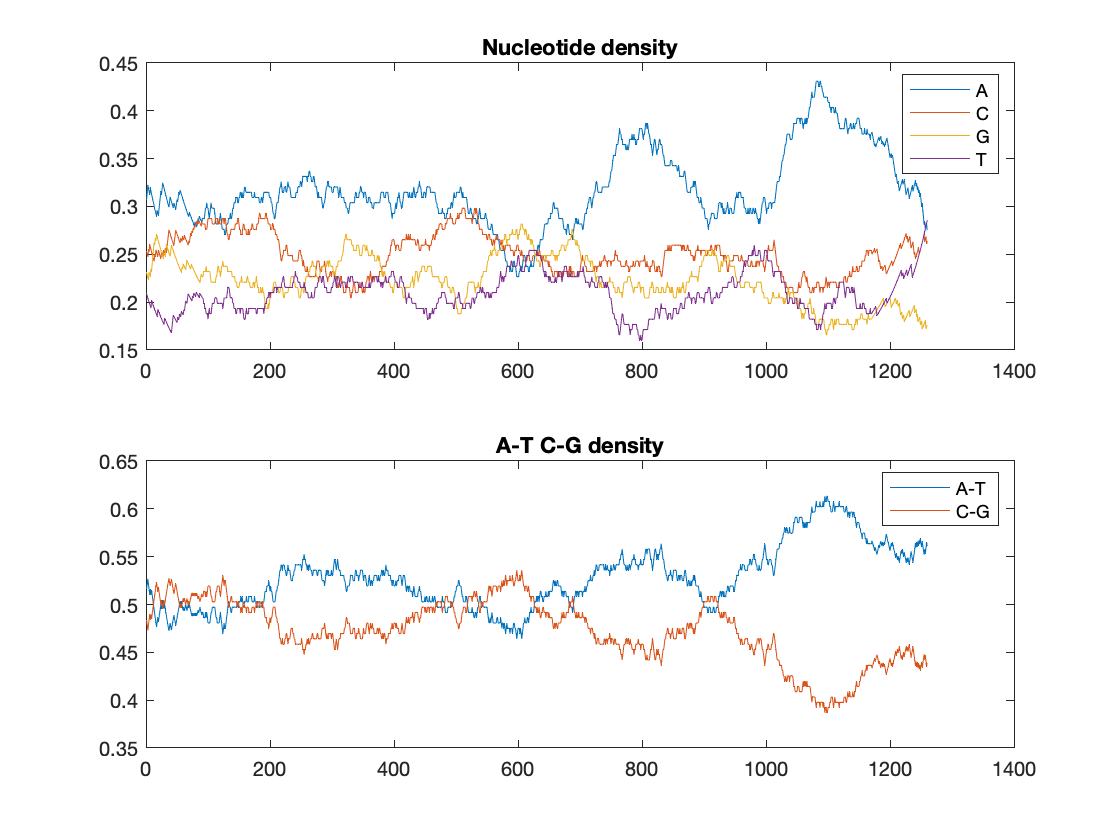

Density_4s = struct with fields:
    A: [0.3077 0.3152 0.3226 0.3191 0.3158 0.3125 0.3196 0.3163 0.3131 0.3100 0.3069 0.3039 0.3010 0.2981 0.2952 0.2925 0.2897 0.2963 0.2936 0.2909 0.2973 0.3036 0.3097 0.3158 0.3130 0.3190 0.3248 0.3220 0.3193 0.3167 0.3140 0.3115 0.3089 0.3065 … ]
    C: [0.2527 0.2500 0.2473 0.2553 0.2526 0.2604 0.2577 0.2551 0.2525 0.2500 0.2475 0.2451 0.2427 0.2500 0.2476 0.2547 0.2523 0.2500 0.2477 0.2545 0.2523 0.2500 0.2478 0.2456 0.2522 0.2500 0.2479 0.2542 0.2521 0.2500 0.2562 0.2541 0.2520 0.2581 … ]
    G: [0.2308 0.2283 0.2258 0.2234 0.2316 0.2292 0.2268 0.2347 0.2323 0.2400 0.2475 0.2549 0.2621 0.2596 0.2667 0.2642 0.2710 0.2685 0.2661 0.2636 0.2613 0.2589 0.2566 0.2544 0.2522 0.2500 0.2479 0.2458 0.2521 0.2500 0.2479 0.2541 0.2602 0.2581 … ]
    T: [0.2088 0.2065 0.2043 0.2021 0.2000 0.1979 0.1959 0.1939 0.2020 0.2000 0.1980 0.1961 0.1942 0.1923 0.1905 0.1887 0.1869 0.1852 0.1927 0.1909 0.1892 0.1875 0.1858 0.1842 0.1826 0.1810 0.1795 0.1780 0.1765 0.1833

figure;
Density_4s = ntdensity(protein, 'Window', 180)

The approximate representation of the division f the different states is shown below: 

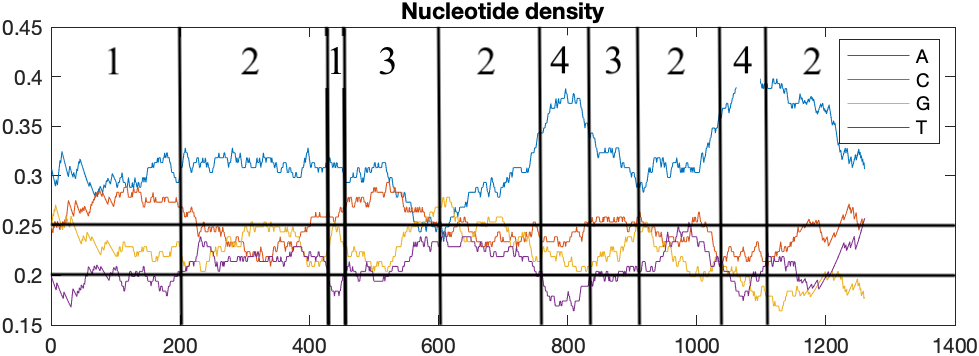

% STATE 1
occ41_A = sum(Density_4s.A(1:200)) + sum(Density_4s.A(420:450));
occ41_C = sum(Density_4s.C(1:200)) + sum(Density_4s.C(420:450));
occ41_G = sum(Density_4s.G(1:200)) + sum(Density_4s.G(420:450));
occ41_T = sum(Density_4s.T(1:200)) + sum(Density_4s.T(420:450));

% STATE 2
occ42_A = sum(Density_4s.A(200:420)) + sum(Density_4s.A(600:780)) + sum(Density_4s.A(900:1020)) + sum(Density_4s.A(1050:lengthProtein));
occ42_C = sum(Density_4s.C(200:420)) + sum(Density_4s.C(600:780)) + sum(Density_4s.C(900:1020)) + sum(Density_4s.C(1050:lengthProtein));
occ42_G = sum(Density_4s.G(200:420)) + sum(Density_4s.G(600:780)) + sum(Density_4s.G(900:1020)) + sum(Density_4s.G(1050:lengthProtein));
occ42_T = sum(Density_4s.T(200:420)) + sum(Density_4s.T(600:780)) + sum(Density_4s.T(900:1020)) + sum(Density_4s.T(1050:lengthProtein));

% STATE 3
occ43_A = sum(Density_4s.A(420:600)) + sum(Density_4s.A(820:900));
occ43_C = sum(Density_4s.C(420:600)) + sum(Density_4s.C(820:900));
occ43_G = sum(Density_4s.G(420:600)) + sum(Density_4s.G(820:900));
occ43_T = sum(Density_4s.T(420:600)) + sum(Density_4s.T(820:900));

% STATE 4
occ44_A = sum(Density_4s.A(780:820)) + sum(Density_4s.A(1020:1050));
occ44_C = sum(Density_4s.C(780:820)) + sum(Density_4s.C(1020:1050));
occ44_G = sum(Density_4s.G(780:820)) + sum(Density_4s.G(1020:1050));
occ44_T = sum(Density_4s.T(780:820)) + sum(Density_4s.T(1020:1050));

% PROBABILITIES 
% STATE 1
prob41_A = occ41_A/sum(Density_4s.A);
prob41_C = occ41_C/sum(Density_4s.C);
prob41_G = occ41_G/sum(Density_4s.G);
prob41_T = occ41_T/sum(Density_4s.T);

% STATE 2
prob42_A = occ42_A/sum(Density_4s.A);
prob42_C = occ42_C/sum(Density_4s.C);
prob42_G = occ42_G/sum(Density_4s.G);
prob42_T = occ42_T/sum(Density_4s.T);

% STATE 3
prob43_A = occ43_A/sum(Density_4s.A);
prob43_C = occ43_C/sum(Density_4s.C);
prob43_G = occ43_G/sum(Density_4s.G);
prob43_T = occ43_T/sum(Density_4s.T);

% STATE 4
prob44_A = occ44_A/sum(Density_4s.A);
prob44_C = occ44_C/sum(Density_4s.C);
prob44_G = occ44_G/sum(Density_4s.G);
prob44_T = occ44_T/sum(Density_4s.T);
% Plot data in a table
E_4 = [[prob41_A, prob41_C, prob41_G, prob41_T];
       [prob42_A, prob42_C, prob42_G, prob42_T];
       [prob43_A, prob43_C, prob43_G, prob43_T];
       [prob44_A, prob44_C, prob44_G, prob44_T]]

E_4 =     0.1748    0.1995    0.1896    0.1704
    0.5906    0.5586    0.5762    0.6056
    0.1990    0.2212    0.2116    0.2017
    0.0664    0.0529    0.0538    0.0517


% Sanity check (= 1)
sum([prob41_A, prob42_A, prob43_A, prob44_A]);
sum([prob41_C, prob42_C, prob43_C, prob44_C]);
sum([prob41_G, prob42_G, prob43_G, prob44_G]);
sum([prob41_T, prob42_T, prob43_T, prob44_T]);

% COMPUTE T
% STATE 1
state41to42 = 1/lengthProtein;
state41to43 = 1/lengthProtein;
state41to44 = 0;
state41to41 = 1 - (state41to42 + state41to43 + state41to44);

% STATE 2
state42to41 = 1/lengthProtein;
state42to43 = 0;
state42to44 = 2/lengthProtein;
state42to42 = 1 - (state42to41 + state42to43 + state42to44);

% STATE 3
state43to41 = 0;
state43to42 = 2/lengthProtein;
state43to44 = 0;
state43to43 = 1 - (state43to41 + state43to42 + state43to44);

% STATE 4
state44to41 = 0;
state44to42 = 1/lengthProtein;
state44to43 = 1/lengthProtein;
state44to44 = 1 - (state44to41 + state44to42 + state44to43);

% Build transition matrix T
T_4 = [[state41to41, state41to42, state41to43, state41to44];
       [state42to41, state42to42, state42to43, state42to44];
       [state43to41, state43to42, state43to43, state43to44];
       [state44to41, state44to42, state44to43, state44to44]]

T_4 =     0.9984    0.0008    0.0008         0
    0.0008    0.9976         0    0.0016
         0    0.0016    0.9984         0
         0    0.0008    0.0008    0.9984


% Train model based on the estimated T and E matrices
[ESTTR_4, ESTEMIT_4] = hmmtrain(int_protein, T_4, E_4)

ESTTR_4 =     0.2322    0.0000    0.7678         0
    0.1621    0.6594         0    0.1786
         0    0.7344    0.2656         0
         0    0.4325    0.3817    0.1858


ESTEMIT_4 =     0.0788    0.0000    0.0000    0.9212
    0.3246    0.3545    0.1682    0.1526
    0.0022    0.2582    0.6678    0.0719
    0.9985    0.0015    0.0000    0.0000


STATES_4 = hmmviterbi(int_protein, ESTTR_4, ESTEMIT_4)

STATES_4 =      1     1     3     2     2     1     3     2     2     2     2     1     3     3     2     2     2     2     2     2     2     2     2     2     2     4     3     2     2     2     2     2     1     3     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     1


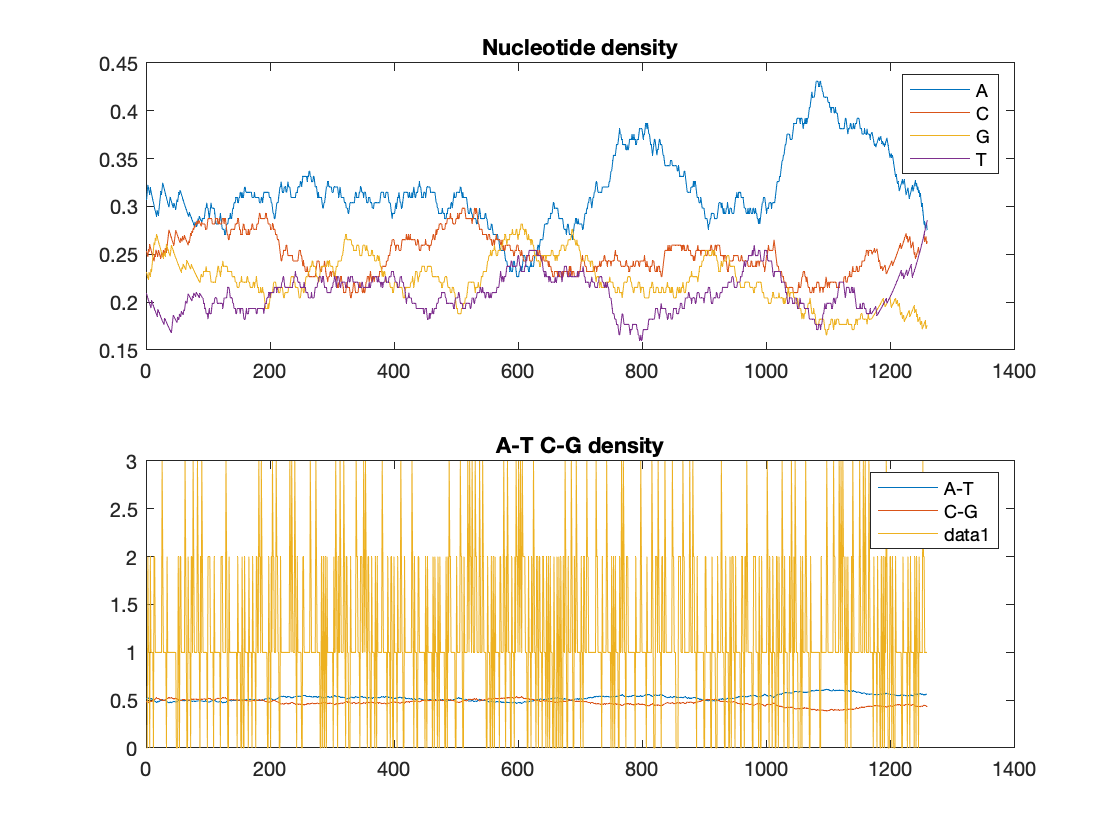

% Plot the resulting matrices E and T after training the model
figure;
ntdensity(protein, 'Window', 180);
hold on;
plot(STATES_4-1)

## Conclusion:

 The following steps are performed for HMMs with 2, 3 and 4 states:

- Determine the different states for each HMM.

- Compute an estimate of the matrix E by evaluating the occurrences the nucleotides A, C, G and T appear in each state.

- Compute an estimate of the matrix T by evaluating how often there is a switch from one state to another (the number of switches is then divided by the total length of the protein to calculate to probability).

- The HMM is trained using the esitmated matrices E and T.

- The result of the previous step is plotted on the density plot to visualize the switches between the different states. 

By looking at the plots of HMMs with different number of states it is possible to conclude that as the states increase, the estimate of the different switches between states improves. Moreover, the sequence is too complex to obtain a clear solution and neat division of the different states since the algorithm does not converge for a very high number of iteration.